# The Quantum Mouse - Part II

[*Matthias Wolff*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/prof-dr-ing-habil-matthias-wolff)

[BTU Cottbus-Senftenberg](https://www.b-tu.de/en/), [Chair of Communications Engineering](https://www.b-tu.de/en/fg-kommunikationstechnik)

## 1   How to Model and Perform Trial Actions on the Inner Stage

**1.1   The Inner Stage**

To be able to interact with the world, our mouse need a suitable model of it in its mind. Following Norbert Bischoff [1], we will call this model the "inner stage". For a simple 3$\times$3 maze world with cheese in the top-right position, the inner stage would look like shown in Fig. 1.

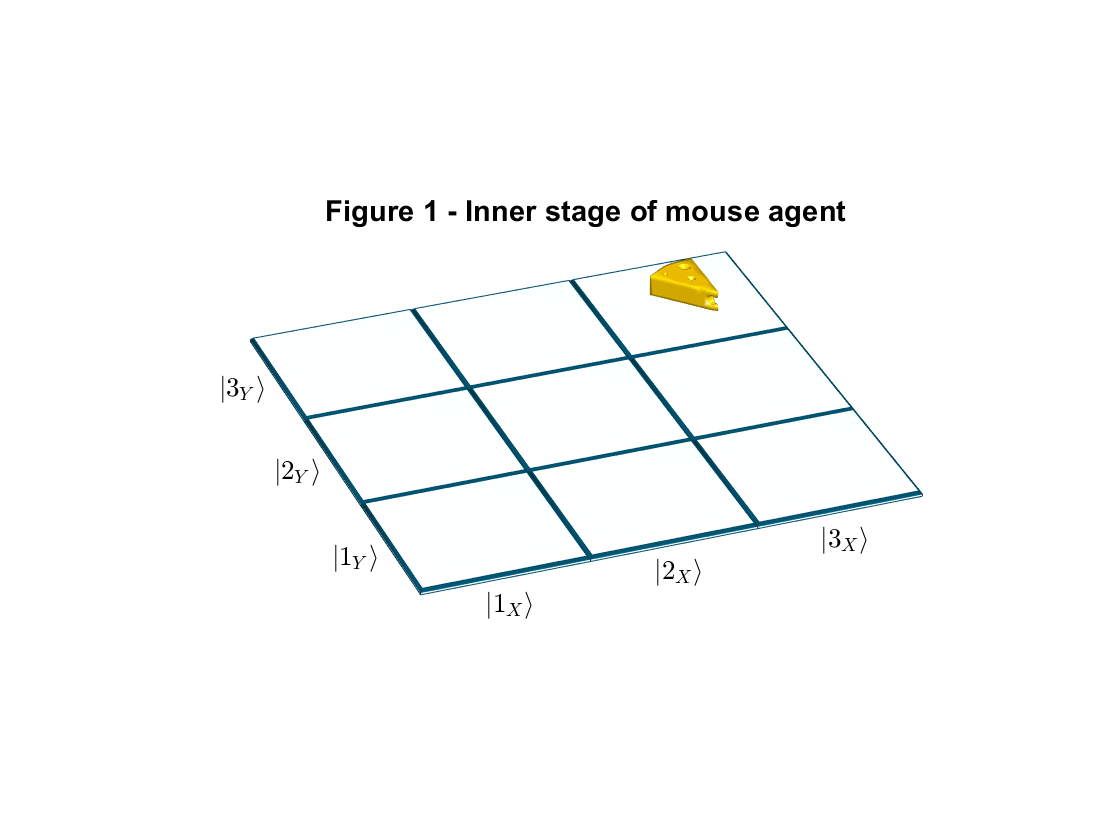

% Add FockBox to path
try
  addFockBoxToPath;
catch
  error('Change to examples folder to run this live script!');
end

%% The maze
%x = 1 2 3  | y=
M = [0 0 1; % 3
     0 0 0; % 2
     0 0 0; % 1
    ];
xdim = size(M,2);
ydim = size(M,1);

% Plot the maze
figure;
mmp = MouseMazePlot([xdim ydim]);
for x=1:xdim
  for y=1:ydim
    if M(ydim-y+1,x)
      mmp.addCheese(x,y);
    end
  end
end
title("Figure 1 - Inner stage of mouse agent");

**1.2   A Fock Space Model of the Inner Stage**

Like in the first part of our quantum mouse example, we build a Fock space describing the world

        
$$H = 
span\big(|1_X\rangle, |2_X\rangle,|3_X\rangle\big)
\otimes
span\big(|1_Y\rangle, |2_Y\rangle,|3_Y\rangle
\otimes
span\big(|0_C\rangle, |1_C\rangle$$


with bases $|n_X\rangle$, $|m_Y\rangle$, and $|l_C\rangle$ for the x and y coordinates of the maze places and the cheese flag. 

X = cell(1,xdim);
Y = cell(1,ydim);
C = cell(1,2);
for i=1:xdim; X{i}=fockobj.bket(i+"X");     end        % X=i bases
for i=1:ydim; Y{i}=fockobj.bket(i+"Y");     end        % Y=i bases
for i=1:2;    C{i}=fockobj.bket((i-1)+"C"); end        % Cheese bases

The actual situation in the maze, aka. the "world ket", is

        
$$|w\rangle
= \bigoplus\limits_{n=1}^N
   \bigoplus\limits_{m=1}^M
  |n_X\, m_Y\, c(x,y)\rangle,$$


where $|c(x,y)\rangle=|1_C\rangle$ iff there is cheese a location $(x,y)$ and $|c(x,y)\rangle=|0_C\rangle$ otherwise. $(N,M)$ denotes the size of the maze.

W = 0;
for i=1:xdim
  for j=1:ydim
    W = W + [ X{i} Y{ydim-j+1} C{M(j,i)+1} ];
  end
end
W.name = 'maze state'; disp(W);

  fockobj

    Name: maze state 
    Type: ket 

    (1X⊗1Y⊗0C,∅)        	1.000000
    (1X⊗2Y⊗0C,∅)        	1.000000
    (1X⊗3Y⊗0C,∅)        	1.000000
    (2X⊗1Y⊗0C,∅)        	1.000000
    (2X⊗2Y⊗0C,∅)        	1.000000
    (2X⊗3Y⊗0C,∅)        	1.000000
    (3X⊗1Y⊗0C,∅)        	1.000000
    (3X⊗2Y⊗0C,∅)        	1.000000
    (3X⊗3Y⊗1C,∅)        	1.000000


We further define  a "veridicality operator"

        
$$O_V = |w\rangle\langle w|$$


describing all possible situations and actions in the world. Veridicality means, that a cognitive model is suitable to describe the real world [1].

OV = W*W'; OV.name = 'veridicality operator'; disp(OV);

  fockobj

    Name: veridicality operator 
    Type: linear operator 

    (1X⊗1Y⊗0C,1X⊗1Y⊗0C) 	1.000000
    (1X⊗2Y⊗0C,1X⊗1Y⊗0C) 	1.000000
    (1X⊗3Y⊗0C,1X⊗1Y⊗0C) 	1.000000
    (2X⊗1Y⊗0C,1X⊗1Y⊗0C) 	1.000000
    (2X⊗2Y⊗0C,1X⊗1Y⊗0C) 	1.000000
    (2X⊗3Y⊗0C,1X⊗1Y⊗0C) 	1.000000
    (3X⊗1Y⊗0C,1X⊗1Y⊗0C) 	1.000000
    (3X⊗2Y⊗0C,1X⊗1Y⊗0C) 	1.000000
    (3X⊗3Y⊗1C,1X⊗1Y⊗0C) 	1.000000
    (1X⊗1Y⊗0C,1X⊗2Y⊗0C) 	1.000000
    (1X⊗2Y⊗0C,1X⊗2Y⊗0C) 	1.000000
    (1X⊗3Y⊗0C,1X⊗2Y⊗0C) 	1.000000
    (2X⊗1Y⊗0C,1X⊗2Y⊗0C) 	1.000000
    (2X⊗2Y⊗0C,1X⊗2Y⊗0C) 	1.000000
    (2X⊗3Y⊗0C,1X⊗2Y⊗0C) 	1.000000
    (3X⊗1Y⊗0C,1X⊗2Y⊗0C) 	1.000000
    (3X⊗2Y⊗0C,1X⊗2Y⊗0C) 	1.000000
    (3X⊗3Y⊗1C,1X⊗2Y⊗0C) 	1.000000
    (1X⊗1Y⊗0C,1X⊗3Y⊗0C) 	1.000000
    (1X⊗2Y⊗0C,1X⊗3Y⊗0C) 	1.000000
    (1X⊗3Y⊗0C,1X⊗3Y⊗0C) 	1.000000
    (2X⊗1Y⊗0C,1X⊗3Y⊗0C) 	1.000000
    (2X⊗2Y⊗0C,1X⊗3Y⊗0C) 	1.000000
    (2X⊗3Y⊗0C,1X⊗3Y⊗0C) 	1.000000
    (3X⊗1Y⊗0C,

% H = [fockspace(X) fockspace(Y) fockspace(C)];
% full(H.sector(3).realize(OV))

## 2   Trial Actions

A trial action is an action to be performed on the inner stage. Trial actions are not necessarily feasible in the real world.

**2.1    Sub-space Operators**

On the $x$ and $y$ coordinate sub-spaces there are two possbile basic operation, increment the coordinate value

        
$$O_{Xinc} = \bigoplus\limits_{n=1}^N |((n\;\;mod\, N)+1)_X\rangle\langle n_X|
\qquad
O_{Yinc} = \bigoplus\limits_{m=1}^M |(m\;\;mod\, M)+1)_Y\rangle\langle n_Y|
$$


and no operation

        
$$O_{Xnop} = \bigoplus\limits_{n=1}^N |n_X\rangle\langle n_X|
\qquad
O_{Ynop} = \bigoplus\limits_{m=1}^M |m_Y\rangle\langle m_Y|.$$


The increment operators are cylic, i.e. incrementing the maximum coordinate value leads back to one. Decrementing is the inverse operation of incrementing

        
$$O_{Xdec} = O_{Xinc}^{-1}
\qquad
O_{Ydec} = O_{Yinc}^{-1}.$$


Oxinc = 0;                                             % Increment X (cyclic)
Oxnop = 0;                                             % Noop on X
for i=1:xdim
  Oxinc = Oxinc + X{rem(i,xdim)+1}*X{i}';
  Oxnop = Oxnop + X{i}*X{i}';
end
Oxdec = inv(Oxinc);
Oxinc.name = 'increment-x operator'; disp(Oxinc);

  fockobj

    Name: increment-x operator 
    Type: linear operator 

    (2X,1X)             	1.000000
    (3X,2X)             	1.000000
    (1X,3X)             	1.000000


Oxdec.name = 'decrement-x operator'; disp(Oxdec);

  fockobj

    Name: decrement-x operator 
    Type: linear operator 

    (3X,1X)             	1.000000
    (1X,2X)             	1.000000
    (2X,3X)             	1.000000


Oxnop.name = 'noop-on-x operator';   disp(Oxnop);

  fockobj

    Name: noop-on-x operator 
    Type: linear operator 

    (1X,1X)             	1.000000
    (2X,2X)             	1.000000
    (3X,3X)             	1.000000



Oyinc = 0;                                             % Increment Y (cyclic)
Oynop = 0;                                             % Noop on Y
for i=1:ydim
  Oyinc = Oyinc + Y{rem(i,ydim)+1}*Y{i}';
  Oynop = Oynop + Y{i}*Y{i}';
end
Oydec = inv(Oyinc);
Oyinc.name = 'increment-y operator'; disp(Oyinc);

  fockobj

    Name: increment-y operator 
    Type: linear operator 

    (2Y,1Y)             	1.000000
    (3Y,2Y)             	1.000000
    (1Y,3Y)             	1.000000


Oydec.name = 'decrement-y operator'; disp(Oydec);

  fockobj

    Name: decrement-y operator 
    Type: linear operator 

    (3Y,1Y)             	1.000000
    (1Y,2Y)             	1.000000
    (2Y,3Y)             	1.000000


Oynop.name = 'noop-on-y operator';   disp(Oynop);

  fockobj

    Name: noop-on-y operator 
    Type: linear operator 

    (1Y,1Y)             	1.000000
    (2Y,2Y)             	1.000000
    (3Y,3Y)             	1.000000


For the cheese flag, there is inversion

        
$$O_{Cinv} = |0_C\rangle\langle1_C|
  \oplus|1_C\rangle\langle0_C|$$


and no operation

        
$$O_{Cnop} = |0_C\rangle\langle0_C|
  \oplus|1_C\rangle\langle1_C|.$$


Ocinv = C{1}*C{2}' + C{2}*C{1}';                       % Invert cheese
Ocnop = C{1}*C{1}' + C{2}*C{2}';                       % Noop on cheese
Ocinv.name = 'invert-cheese operator';  disp(Ocinv);

  fockobj

    Name: invert-cheese operator 
    Type: linear operator 

    (1C,0C)             	1.000000
    (0C,1C)             	1.000000


Ocnop.name = 'noop-on-cheese operator'; disp(Ocnop);

  fockobj

    Name: noop-on-cheese operator 
    Type: linear operator 

    (0C,0C)             	1.000000
    (1C,1C)             	1.000000


**2.2   Generic and Veridical Movement Trial Actions**

Movement in the direction of one of the cardinal points N, E, S, or W is a tensor product of suitable sub-space operators on the $x$ and $y$ coordinate spaces. To be applicable to the Fock space of the inner stage, we need a third factor: the cheese operation. The problem with the latter is that cheese depends on the location $(x,y)$ and we do not know whether to use $O_{Cinv}$ or $O_{Cnop}$ for a movement operator. Hence we use the superposition $O_{Cinv}\oplus O_{Cnop}$ to define generic east and North operators (we will take care for east and south in a moment)

        
$$\tilde{O}_E = O_{Xinc}\otimes O_{Ynop}\otimes(O_{Cinv}\oplus O_{Cnop}),
\qquad
\tilde{O}_N = O_{Xnop}\otimes O_{Yinc}\otimes(O_{Cinv}\oplus O_{Cnop}).
\$$


OE = [Oxinc Oynop (Ocinv+Ocnop)];
ON = [Oxnop Oyinc (Ocinv+Ocnop)];
OE.name = 'generic go-east operator';  disp(OE);

  fockobj

    Name: generic go-east operator 
    Type: linear operator 

    (2X⊗1Y⊗0C,1X⊗1Y⊗0C) 	1.000000
    (2X⊗1Y⊗1C,1X⊗1Y⊗0C) 	1.000000
    (2X⊗1Y⊗0C,1X⊗1Y⊗1C) 	1.000000
    (2X⊗1Y⊗1C,1X⊗1Y⊗1C) 	1.000000
    (2X⊗2Y⊗0C,1X⊗2Y⊗0C) 	1.000000
    (2X⊗2Y⊗1C,1X⊗2Y⊗0C) 	1.000000
    (2X⊗2Y⊗0C,1X⊗2Y⊗1C) 	1.000000
    (2X⊗2Y⊗1C,1X⊗2Y⊗1C) 	1.000000
    (2X⊗3Y⊗0C,1X⊗3Y⊗0C) 	1.000000
    (2X⊗3Y⊗1C,1X⊗3Y⊗0C) 	1.000000
    (2X⊗3Y⊗0C,1X⊗3Y⊗1C) 	1.000000
    (2X⊗3Y⊗1C,1X⊗3Y⊗1C) 	1.000000
    (3X⊗1Y⊗0C,2X⊗1Y⊗0C) 	1.000000
    (3X⊗1Y⊗1C,2X⊗1Y⊗0C) 	1.000000
    (3X⊗1Y⊗0C,2X⊗1Y⊗1C) 	1.000000
    (3X⊗1Y⊗1C,2X⊗1Y⊗1C) 	1.000000
    (3X⊗2Y⊗0C,2X⊗2Y⊗0C) 	1.000000
    (3X⊗2Y⊗1C,2X⊗2Y⊗0C) 	1.000000
    (3X⊗2Y⊗0C,2X⊗2Y⊗1C) 	1.000000
    (3X⊗2Y⊗1C,2X⊗2Y⊗1C) 	1.000000
    (3X⊗3Y⊗0C,2X⊗3Y⊗0C) 	1.000000
    (3X⊗3Y⊗1C,2X⊗3Y⊗0C) 	1.000000
    (3X⊗3Y⊗0C,2X⊗3Y⊗1C) 	1.000000
    (3X⊗3Y⊗1C,2X⊗3Y⊗1C) 	1.000000
    (1X⊗1Y⊗

ON.name = 'generic go-north operator'; disp(ON);

  fockobj

    Name: generic go-north operator 
    Type: linear operator 

    (1X⊗2Y⊗0C,1X⊗1Y⊗0C) 	1.000000
    (1X⊗2Y⊗1C,1X⊗1Y⊗0C) 	1.000000
    (1X⊗2Y⊗0C,1X⊗1Y⊗1C) 	1.000000
    (1X⊗2Y⊗1C,1X⊗1Y⊗1C) 	1.000000
    (1X⊗3Y⊗0C,1X⊗2Y⊗0C) 	1.000000
    (1X⊗3Y⊗1C,1X⊗2Y⊗0C) 	1.000000
    (1X⊗3Y⊗0C,1X⊗2Y⊗1C) 	1.000000
    (1X⊗3Y⊗1C,1X⊗2Y⊗1C) 	1.000000
    (1X⊗1Y⊗0C,1X⊗3Y⊗0C) 	1.000000
    (1X⊗1Y⊗1C,1X⊗3Y⊗0C) 	1.000000
    (1X⊗1Y⊗0C,1X⊗3Y⊗1C) 	1.000000
    (1X⊗1Y⊗1C,1X⊗3Y⊗1C) 	1.000000
    (2X⊗2Y⊗0C,2X⊗1Y⊗0C) 	1.000000
    (2X⊗2Y⊗1C,2X⊗1Y⊗0C) 	1.000000
    (2X⊗2Y⊗0C,2X⊗1Y⊗1C) 	1.000000
    (2X⊗2Y⊗1C,2X⊗1Y⊗1C) 	1.000000
    (2X⊗3Y⊗0C,2X⊗2Y⊗0C) 	1.000000
    (2X⊗3Y⊗1C,2X⊗2Y⊗0C) 	1.000000
    (2X⊗3Y⊗0C,2X⊗2Y⊗1C) 	1.000000
    (2X⊗3Y⊗1C,2X⊗2Y⊗1C) 	1.000000
    (2X⊗1Y⊗0C,2X⊗3Y⊗0C) 	1.000000
    (2X⊗1Y⊗1C,2X⊗3Y⊗0C) 	1.000000
    (2X⊗1Y⊗0C,2X⊗3Y⊗1C) 	1.000000
    (2X⊗1Y⊗1C,2X⊗3Y⊗1C) 	1.000000
    (3X⊗2Y

To make the operators veridical, i.e. including the correct cheese flag at the target location, we compute the Hadamard products of the veridicality operator $O_V$ and the generic movement operators

        
$$O_E=O_V\circ \tilde{O}_E,
\qquad
O_N=O_V\circ \tilde{O}_N.$$


The veridical go-west and go-south movement operators are the inverses of the veridical go-east and go-north operators, respectively

        
$$O_W=O_E^{-1},
\qquad
O_S=O_N^{-1}.$$


OE = OV.*OE;                                           % Veridical go-east operator
ON = OV.*ON;                                           % Veridical go-east operator
OW = inv(OE);                                          % Go-west is the inverse of go-east
OS = inv(ON);                                          % Go-south is the inverse of go-north
OE.name = 'veridical go-east operator';  disp(OE);

  fockobj

    Name: veridical go-east operator 
    Type: linear operator 

    (2X⊗1Y⊗0C,1X⊗1Y⊗0C) 	1.000000
    (2X⊗2Y⊗0C,1X⊗2Y⊗0C) 	1.000000
    (2X⊗3Y⊗0C,1X⊗3Y⊗0C) 	1.000000
    (3X⊗1Y⊗0C,2X⊗1Y⊗0C) 	1.000000
    (3X⊗2Y⊗0C,2X⊗2Y⊗0C) 	1.000000
    (3X⊗3Y⊗1C,2X⊗3Y⊗0C) 	1.000000
    (1X⊗1Y⊗0C,3X⊗1Y⊗0C) 	1.000000
    (1X⊗2Y⊗0C,3X⊗2Y⊗0C) 	1.000000
    (1X⊗3Y⊗0C,3X⊗3Y⊗1C) 	1.000000


ON.name = 'veridical go-north operator'; disp(ON); 

  fockobj

    Name: veridical go-north operator 
    Type: linear operator 

    (1X⊗2Y⊗0C,1X⊗1Y⊗0C) 	1.000000
    (1X⊗3Y⊗0C,1X⊗2Y⊗0C) 	1.000000
    (1X⊗1Y⊗0C,1X⊗3Y⊗0C) 	1.000000
    (2X⊗2Y⊗0C,2X⊗1Y⊗0C) 	1.000000
    (2X⊗3Y⊗0C,2X⊗2Y⊗0C) 	1.000000
    (2X⊗1Y⊗0C,2X⊗3Y⊗0C) 	1.000000
    (3X⊗2Y⊗0C,3X⊗1Y⊗0C) 	1.000000
    (3X⊗3Y⊗1C,3X⊗2Y⊗0C) 	1.000000
    (3X⊗1Y⊗0C,3X⊗3Y⊗1C) 	1.000000


OW.name = 'veridical go-west operator';  disp(OW);

  fockobj

    Name: veridical go-west operator 
    Type: linear operator 

    (3X⊗1Y⊗0C,1X⊗1Y⊗0C) 	1.000000
    (3X⊗2Y⊗0C,1X⊗2Y⊗0C) 	1.000000
    (3X⊗3Y⊗1C,1X⊗3Y⊗0C) 	1.000000
    (1X⊗1Y⊗0C,2X⊗1Y⊗0C) 	1.000000
    (1X⊗2Y⊗0C,2X⊗2Y⊗0C) 	1.000000
    (1X⊗3Y⊗0C,2X⊗3Y⊗0C) 	1.000000
    (2X⊗1Y⊗0C,3X⊗1Y⊗0C) 	1.000000
    (2X⊗2Y⊗0C,3X⊗2Y⊗0C) 	1.000000
    (2X⊗3Y⊗0C,3X⊗3Y⊗1C) 	1.000000


OS.name = 'veridical go-south operator'; disp(OS); 

  fockobj

    Name: veridical go-south operator 
    Type: linear operator 

    (1X⊗3Y⊗0C,1X⊗1Y⊗0C) 	1.000000
    (1X⊗1Y⊗0C,1X⊗2Y⊗0C) 	1.000000
    (1X⊗2Y⊗0C,1X⊗3Y⊗0C) 	1.000000
    (2X⊗3Y⊗0C,2X⊗1Y⊗0C) 	1.000000
    (2X⊗1Y⊗0C,2X⊗2Y⊗0C) 	1.000000
    (2X⊗2Y⊗0C,2X⊗3Y⊗0C) 	1.000000
    (3X⊗3Y⊗1C,3X⊗1Y⊗0C) 	1.000000
    (3X⊗1Y⊗0C,3X⊗2Y⊗0C) 	1.000000
    (3X⊗2Y⊗0C,3X⊗3Y⊗1C) 	1.000000


## 3   Performing Trial Actions on the Inner Stage

**3.1   Preparing a Veridical Mouse State**

First we set the mouse at location $(1,1)$ into the inner stage by preparing a generic mouse state

        
$$|\tilde{\varphi}\rangle = |1_X\;1_Y\;(0_C\oplus 1_C)\rangle$$


and making it veridical

        
$$|\varphi\rangle = |w\rangle\circ|\tilde{\varphi}\rangle.$$


phi = [X{1} Y{1} (C{1}+C{2})];                         % @(X=1,Y=1,C=?)
phi = W.*phi;                                          % Get cheese value @(1,1)
phi.name = 'mouse state'; disp(phi);

  fockobj

    Name: mouse state 
    Type: ket 

    (1X⊗1Y⊗0C,∅)        	1.000000


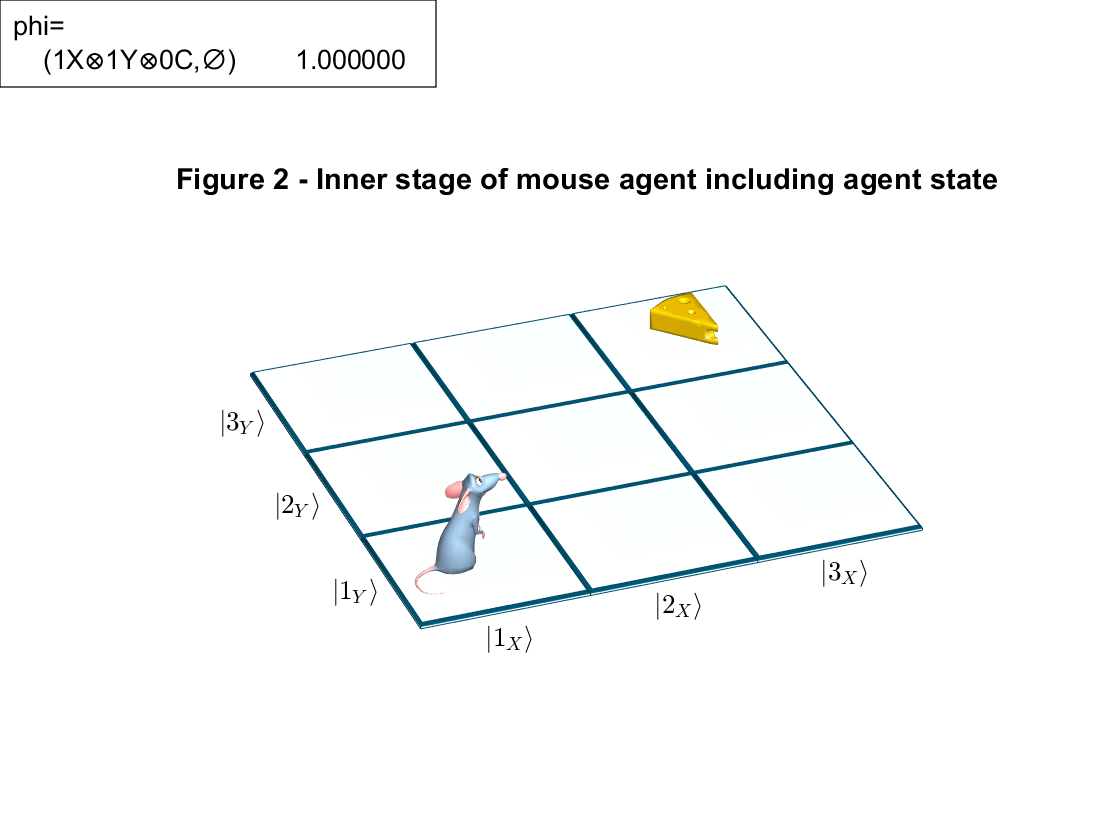


tbox = annotation('textbox',[0 0.9 0.1 0.1],'FitBoxToText','on');
measureMouse(phi,X,Y,C,mmp,tbox);
title('Figure 2 - Inner stage of mouse agent including agent state');

**3.2   Moving Around**

Moving the mouse is just multiplying its state ket $|\varphi\rangle$ with one of the veridical movement operators $O_N$, $O_E$, $O_S$, or $O_W$ or arbitrary products of them, e.g.,

        
$$|\varphi\rangle\gets O_E\,O_E\,O_N\,O_N\cdot|\varphi\rangle.$$


phi = OE*OE*ON*ON*phi;                                 % Go east,east,north,north
phi.name = 'mouse state';               disp(phi);

  fockobj

    Name: mouse state 
    Type: ket 

    (3X⊗3Y⊗1C,∅)        	1.000000


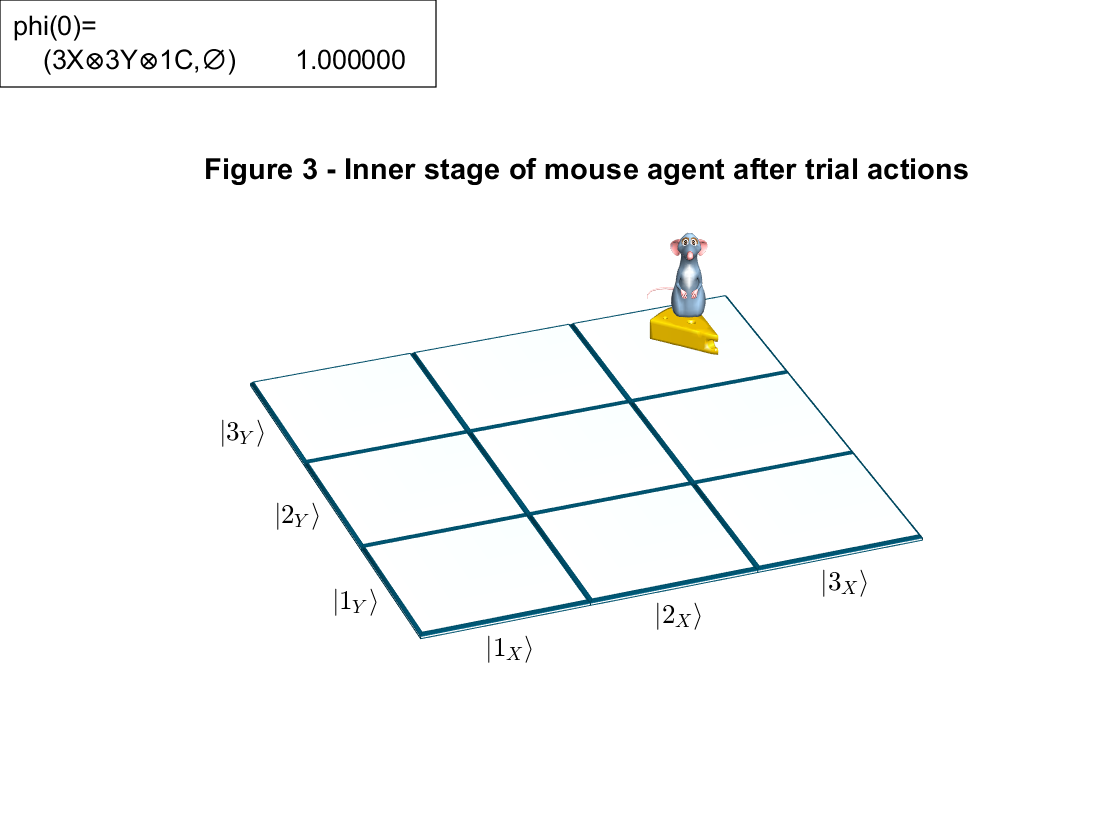

measureMouse(phi,X,Y,C,mmp,tbox,0,0);
title('Figure 3 - Inner stage of mouse agent after trial actions')

Now you try interactively ...

drawnow; set(gcf,'Visible','on','WindowStyle','Docked'); figure(gcf);
drawnow; commandwindow; clc;
k = 1;
while true
  if k==1
    d = input('Enter ''N'', ''E'', ''S'', ''W'', or ''q'' to quit\nGo: ','s');
  else
    d = input('Go: ','s');
  end
  h = 90;
  if     strcmpi(d,'q'); break;
  elseif strcmpi(d,'N'); phi = ON*phi; h =   0;
  elseif strcmpi(d,'E'); phi = OE*phi; h =  90; 
  elseif strcmpi(d,'S'); phi = OS*phi; h = 180;
  elseif strcmpi(d,'W'); phi = OW*phi; h = -90;
  end
  phi.name = 'mouse state';
  measureMouse(phi,X,Y,C,mmp,tbox,h,k);
  k = k+1;
end
close gcf;

## Local Functions

The `measureMouse` function measures and displays the current mouse position.

function measureMouse(phi,X,Y,C,mmp,tbox,h,k)
  if nargin<7; h = 90; end
  if nargin<8; k = -1; end
  for i=1:length(X)
    for j=1:length(Y)
      PL = [X{i} Y{j} (C{1}+C{2})] * [X{i} Y{j} (C{1}+C{2})]';
      p = phi' * PL *phi;
      mmp.addMouse(i,j,p,h);
    end
  end
  s = splitlines(evalc('disp(phi);'));
  if k>=0
    tbox.String = [ {sprintf('phi(%d)=',k)}; s(6:length(s)-1) ];
  else
    tbox.String = [ {'phi='}; s(6:length(s)-1) ];
  end
end

## References

[1] N. Bischoff: *Psychologie, Ein Grundkurs für Anspruchsvolle*. Verlag Kohlhammer, 2009, 2. Auflage.